# Avaliação 1

        1. Considere a sequência x[n] = [6 8 5 4 5 6]. Implemente o algoritmo da transformada de Fourier Discreta (DFT) para analisar o espectro frequencial desse sinal e valide osresultados com a função fft do MATLAB.

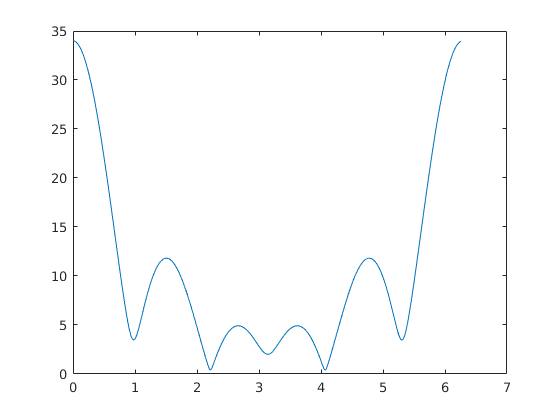

N = 256;
w = [];
for k = 0:N-1
    w = [w (2*pi/N)*k];
end

x = [6 8 5 4 5 6 zeros(1, N-6)];
Xdft = zeros(1, N);
for k = 0:N-1
    for n = 0:N-1
        Xdft(k+1) = Xdft(k+1) + x(n+1)*exp(-i*(2*pi/N)*k*n);
    end
end
plot(w, abs(Xdft));


Xfft = fft(x);
plot(w, abs(X));

        2. Implemente também a transformada discreta inversa de Fourier (IDFT) para restaurar a                 sequência original.

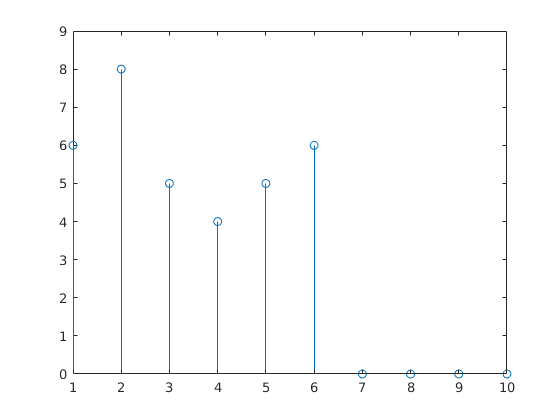

xidft = zeros(1, N);
for n = 0:N-1
    for k = 0:N-1
        xidft(n+1) = xidft(n+1) + (1/N)*Xdft(k+1)*exp(i*(2*pi/N)*k*n);
    end
end
stem(abs(xidft(1:10)));

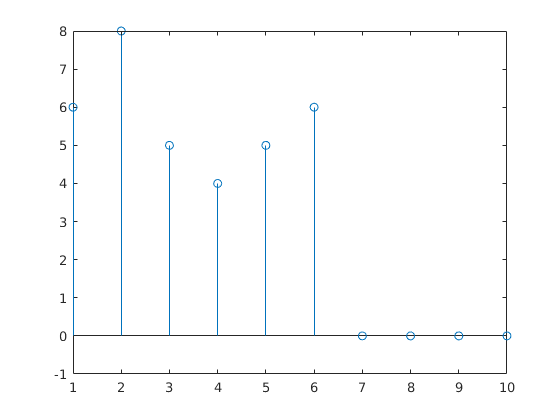


xifft = ifft(Xfft);
stem(xifft(1:10));